# ECSE 343:Assignment 4

Name: Simon Li    

Student Id. 260984998

Due Date: 13 April 2023

## Question 1 :  

a. Write a steepest descent algorithm to solve a linear system  $\textbf A \textbf x = \textbf b$,  where $\textbf A \in \mathbb{R}^{n \times n}$ is a symmetric and positive deifnite matrix, $\textbf b \in \mathbb{R}^{n \times 1}$ and $\textbf x \in \mathbb{R}^{n \times 1}$. You can use the stencil of a function provided in the appendix. (10 marks)

% Write your code in the appendix.

b. Given a linear system  $\textbf A \textbf x = \textbf b$, where $A=\;\left\lbrack \begin{array}{ccc}
10 & 5 & 2\\
5 & 3 & 2\\
2 & 2 & 3
\end{array}\right\rbrack$.  $\textbf A$ is a symmeteric and positive definite matrix. The vector b is given as follows,  $\mathit{\mathbf{b}}=\left\lbrack \begin{array}{c}
2\\
5\\
9
\end{array}\right\rbrack$.

Solve the above system using the steepest descent method your wrote in part a.  In order to validate your answer you can use the LU decomposition method.   (2 marks)

A = [10 5 2;  5 3 2; 2 2 3];
b =[2 5 9]';

% lets also measure  the time taken by each method. This can be done by
% using the tic-toc method. You can see the details of this methods in
% MATLAB documents. We are doing it here to  demonstrate the tic-toc method
% below.

tstart_sd = tic;  % start measuring the time 
[x_sd, iter] = my_steepest_descent(A, b, zeros(3,1), 1e-6, 1000);
time_taken_sd = toc(tstart_sd);  % measure the total time taken by steepest descent method 

tstart_lu = tic;  % start measuring the time 
[L, U,P] = lu(A);
y = (L\(P*b)); %  forward substitution
x_lu = U\y;    % backward substitution
time_taken_sd = toc(tstart_sd);  % measure the total time taken by LU dec


% check the difference between the solution found by  LU decomposition + Forward/Backward Sub
% and  the steepest descent
difference = x_lu -x_sd
norm_difference = norm(difference)


c. In this question, you will solve the matrix systems of size ranging for n= 2, 3, 4 , 5, ..., 100 .  Use the function named *getSystemMatrix_with_lowerConditionNumber* (provided in the appendix) to  generate the system matrix $\textbf A$ and the vector $\textbf b$ of  size n.  The matrix $\textbf A$ generated by the *getSystemMatrix_with_lowerConditionNumber.m* has a good condition number.

Use the LU decomposition based method and the steepest descent method  to compute the solution of linear system with size ranging from n =2  to 100.  Plot the time taken to compute the solution by the LU decompostion based method vs the matrix size. On the same figure, plot the time taken by Steepest Descent method to find the solution.  Label the axes of the plot and include the legend.

Which method takes more time to compute the solution?

Use the cell below to write your code. For measuring  the time taken by each method you can use the code provided in part  b and then change it accordingly.   (8 marks)

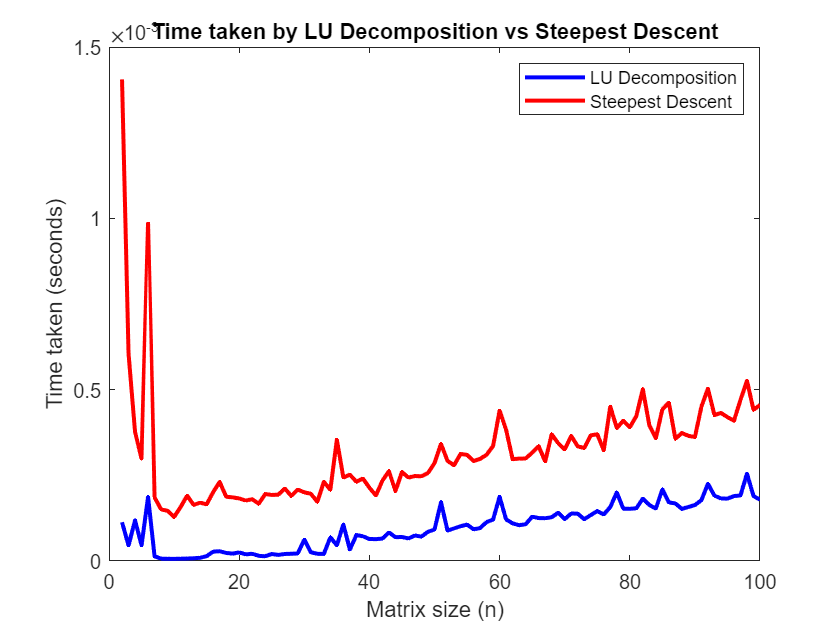

clear all
% write your code here 
% Initialize arrays to store time taken for each method
lu_times = zeros(1, 100);
steepest_descent_times = zeros(1, 100);

% Loop over matrix sizes from 2 to 100
for n = 2:100
    % Generate system matrix and vector
    [A, b] = getSystemMatrix_with_lowerConditionNumber(n);
    
    % Solve the system using LU decomposition
    tic;
    x_lu = A \ b;
    lu_times(n) = toc;
    
    % Solve the system using steepest descent method
    Xguess = zeros(n, 1);
    tol = 1e-6;
    maxiter = 1000;
    tic;
    [x_sd, ~] = my_steepest_descent(A, b, Xguess, tol, maxiter);
    steepest_descent_times(n) = toc;
end
% Plot time taken for both methods
figure;
plot(2:100, lu_times(2:100), 'b', 'LineWidth', 2);
hold on;
plot(2:100, steepest_descent_times(2:100), 'r', 'LineWidth', 2);
xlabel('Matrix size (n)');
ylabel('Time taken (seconds)');
legend('LU Decomposition', 'Steepest Descent');
title('Time taken by LU Decomposition vs Steepest Descent');

In general the LU method seems faster, except for a few values of n where it has a high peak. I think this is because for relatively small matrix sizes (n = 2 to 100), the computational cost of the LU decomposition-based method may not be significantly affected by the matrix size. The direct factorization approach used by LU decomposition does not rely on iteration or convergence, and as a result, its performance may remain relatively stable even as the matrix size increases. In contrast, the steepest descent method is an iterative approach, and its performance can vary depending on the number of iterations needed for convergence.

*d. *In this part you will repeat part c,  however, this time you need to solve the matrix systems of size ranging from n= 2 to 1000.

Similar to part c, plot the time taken by LU decomposition based solver and the steepest descent for each matrix size. Make sure your plots are properly labeled. On a seperate plot also plot the number of iterations taken by steepest decent vs matrix size.

Compare the plots from part c and d, which method takes more time to compute the solution?

Use the cell below to write your code. (5 marks)

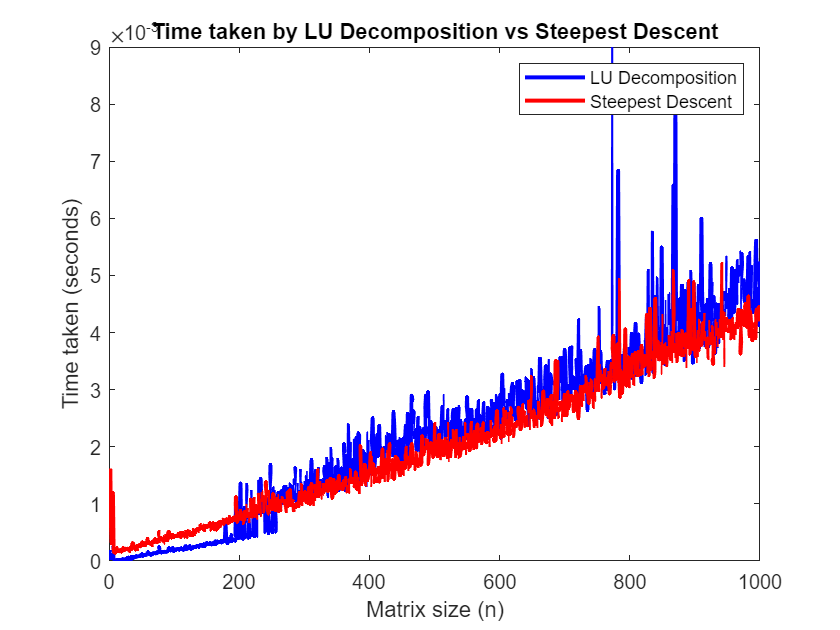

clear all

% Initialize arrays to store time taken for each method and number of iterations
lu_times = zeros(1, 1000);
steepest_descent_times = zeros(1, 1000);
steepest_descent_iters = zeros(1, 1000);

% Loop over matrix sizes from 2 to 1000
for n = 2:1000
    % Generate system matrix and vector
    [A, b] = getSystemMatrix_with_lowerConditionNumber(n);
    
    % Solve the system using LU decomposition
    tic;
    x_lu = A \ b;
    lu_times(n) = toc;
    
    % Solve the system using steepest descent method
    Xguess = zeros(n, 1);
    tol = 1e-6;
    maxiter = 1000;
    tic;
    [x_sd, iters] = my_steepest_descent(A, b, Xguess, tol, maxiter);
    steepest_descent_times(n) = toc;
    steepest_descent_iters(n) = iters;
end

% Plot time taken for both methods
figure;
plot(2:1000, lu_times(2:1000), 'b', 'LineWidth', 2);
hold on;
plot(2:1000, steepest_descent_times(2:1000), 'r', 'LineWidth', 2);
xlabel('Matrix size (n)');
ylabel('Time taken (seconds)');
legend('LU Decomposition', 'Steepest Descent');
title('Time taken by LU Decomposition vs Steepest Descent');

On this plot the steepest descent method seems to take less time to compute the solution and the computation time fluctuates less overall. This makes sense since the steepest descent method is an iterative method that is sensitive to the condition number of the matrix. When the matrix has a lower condition number, the algorithm converges faster, resulting in fewer iterations and less computation time.

e. Similar to the previous part*, *you need to solve the matrix systems of size ranging from n= 2 to 1000.  

Instead this time you will use the function *getSystemMatrix_with_higherConditionNumber *to generate the system matrix $\textbf A$* and vector *$\textbf b$*. T*he function is provided in the appendix. The function, *getSystemMatrix_with_higherConditionNumber, * generates the system matrix $\textbf A$  which has a slightly higher condition number than the matrix you used in parts c and d.

Plot the time taken by LU  decomposition based solver and the steepest descent for each matrix size. Also plot the number of iterations taken by steepest decent vs matrix size.

Comment on the similarities and difference between the  plots from part d and e.

You can use the cell below to write your code. (5 marks)

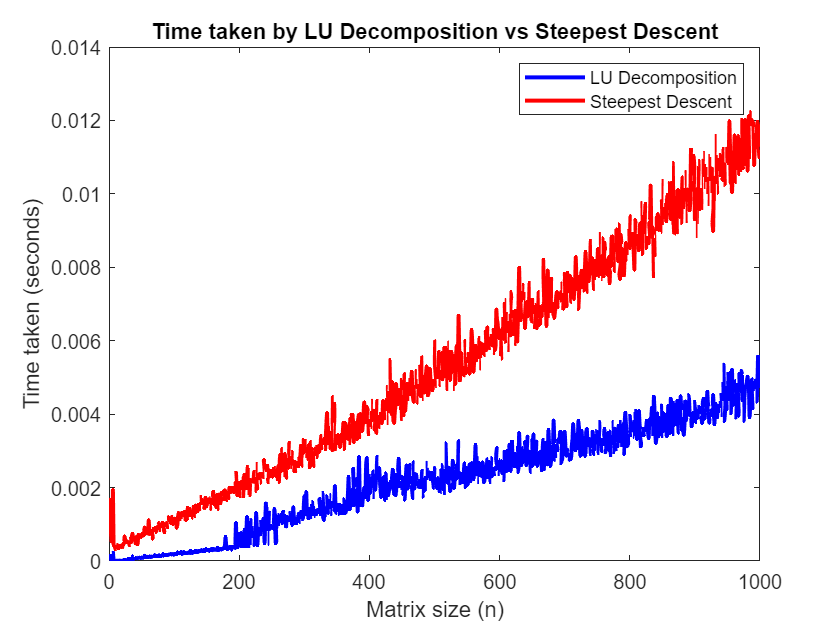

clear all

% Initialize arrays to store time taken for each method and number of iterations
lu_times = zeros(1, 1000);
steepest_descent_times = zeros(1, 1000);
steepest_descent_iters = zeros(1, 1000);

% Loop over matrix sizes from 2 to 1000
for n = 2:1000
    % Generate system matrix and vector
    [A, b] = getSystemMatrix_with_higherConditionNumber(n);
    
    % Solve the system using LU decomposition
    tic;
    x_lu = A \ b;
    lu_times(n) = toc;
    
    % Solve the system using steepest descent method
    Xguess = zeros(n, 1);
    tol = 1e-6;
    maxiter = 1000;
    tic;
    [x_sd, iters] = my_steepest_descent(A, b, Xguess, tol, maxiter);
    steepest_descent_times(n) = toc;
    steepest_descent_iters(n) = iters;
end

% Plot time taken for both methods
figure;
plot(2:1000, lu_times(2:1000), 'b', 'LineWidth', 2);
hold on;
plot(2:1000, steepest_descent_times(2:1000), 'r', 'LineWidth', 2);
xlabel('Matrix size (n)');
ylabel('Time taken (seconds)');
legend('LU Decomposition', 'Steepest Descent');
title('Time taken by LU Decomposition vs Steepest Descent');

In comparison to the plot from part d (lower condition number), the plot for part e (higher condition number) shows a larger difference in computation time between the LU decomposition-based method and the steepest descent method. The LU decomposition method exhibits more stable performance, with computation time primarily depending on the matrix size, while the steepest descent method would show increased computation time due to the higher condition numbers. This makes sense since the steepest descent algorithm's convergence rate is determined by the condition number of the matrix. The higher the condition number, the more iterations are needed, resulting in increased computation time.

## Appendix 

function [A,b]= getSystemMatrix_with_lowerConditionNumber(n)
%  n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.


    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.25);
    A= R'*R;
    b = rand(n,1);
end

function [A,b]= getSystemMatrix_with_higherConditionNumber(n)
%  n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.


    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.15);
    A= R'*R;
    b = rand(n,1);
end

Write your steepest descent here.

function [x, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter)
% inputs: A- a symmeteric and positiv definite matrix.
%         b : RHS vector
%         Xguess: Initial guess 
%         tol : tolerance 
%         maxiter:maximum iterations 
%
% outputs:  x: solution of the system Ax =b
%           iter: number of iterations it took to converge

% Initialization
x = Xguess;
r = b - A * x;
iter = 0;

% Check if the initial guess is already within the tolerance
if norm(r) < tol
    return;
end

% Steepest descent algorithm
while iter < maxiter
    iter = iter + 1;
    
    % Compute the step size (alpha)
    alpha = (r' * r) / (r' * A * r);
    
    % Update the solution
    x = x + alpha * r;
    
    % Compute the new residual
    r = b - A * x;
    
    % Check for convergence
    if norm(r) < tol
        break;
    end
end

end
